## Encontrar a Waldo mediante su espectro de fourier

## Leer las imagenes

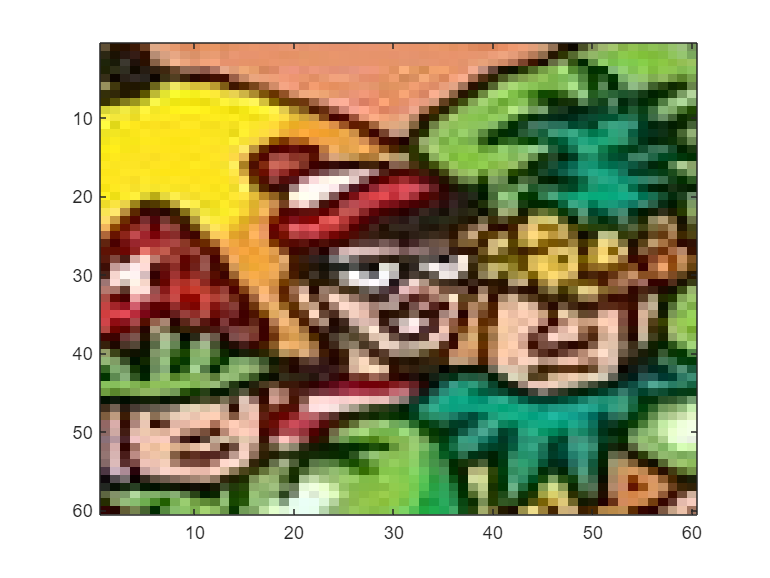

clue = imread("c_clue.jpg");
% Color to grayscale
clueBW = rgb2gray(clue);
% display Image
imagesc(clue)

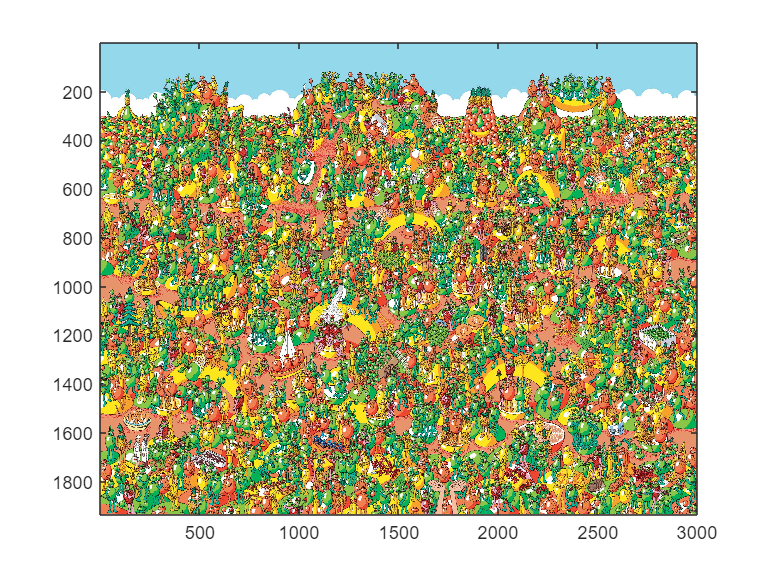

landscape = imread("c.jpg");
landscapeBW = rgb2gray(landscape);
imagesc(landscape)
colormap("gray")

% Tamaño de landscape
[h,w] = size(landscapeBW)

h = 1933

w = 3000

## Mediante sistema 4f

Una manera de realizar la correlacion optica entre imagenes es mediante el sistema 4f, se hace pasar la imagen que contiene a waldo (landscape) y en el plano de fourier se coloca un filtro con forma de la conjugada de la transformada de fourier de la imagen de waldo (clue) y a la salida se espera la correlacion entre las dos imagenes.

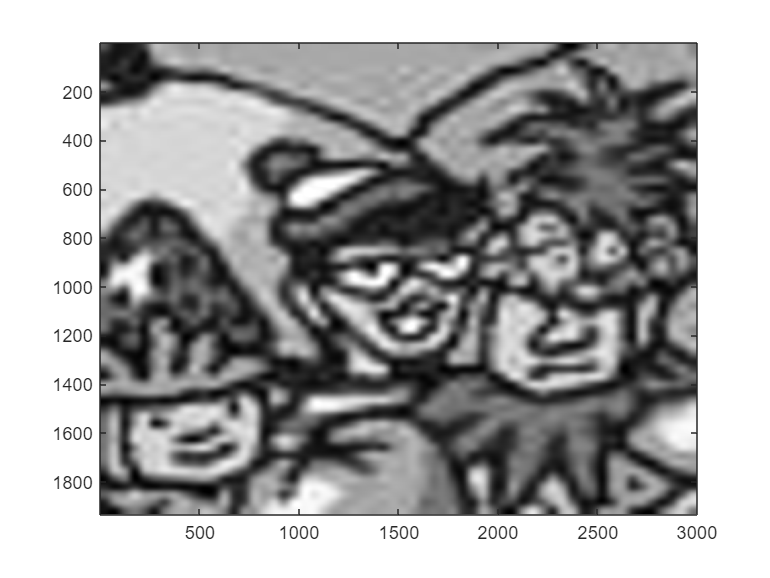


% Intento 1: Poniendo clue del mismo tamaño que landscape

 
clueSameSize = imresize(clueBW,[h w]);
imagesc(clueSameSize)

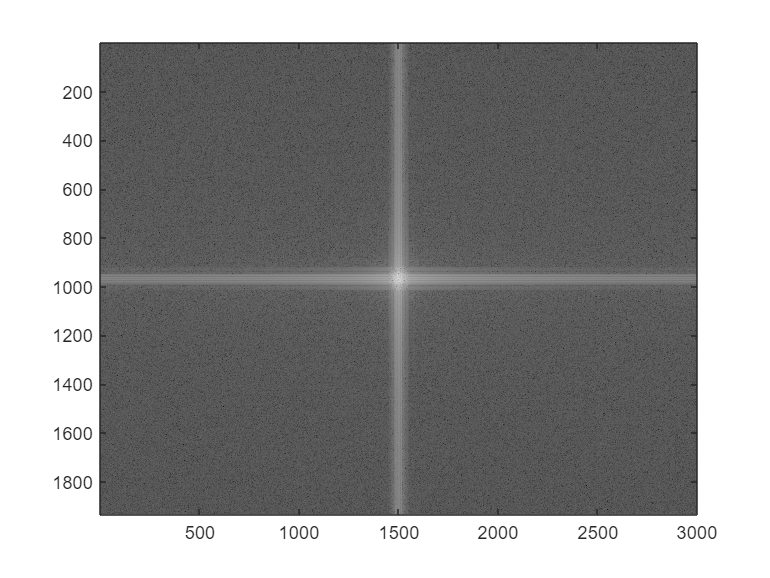

fourierFilterClue = fftshift(fft2(clueSameSize));
imagesc(log(abs(fourierFilterClue)))


% Se hace pasar landscape por el sistema 4f
[~, correlacionOpticaObservable] = sistema4f(landscapeBW, conj(fourierFilterClue));
[maxY,maxX] = find(correlacionOpticaObservable(1:end,:)== max(correlacionOpticaObservable(1:end,:),[],'all'))

maxY = 23

maxX = 700

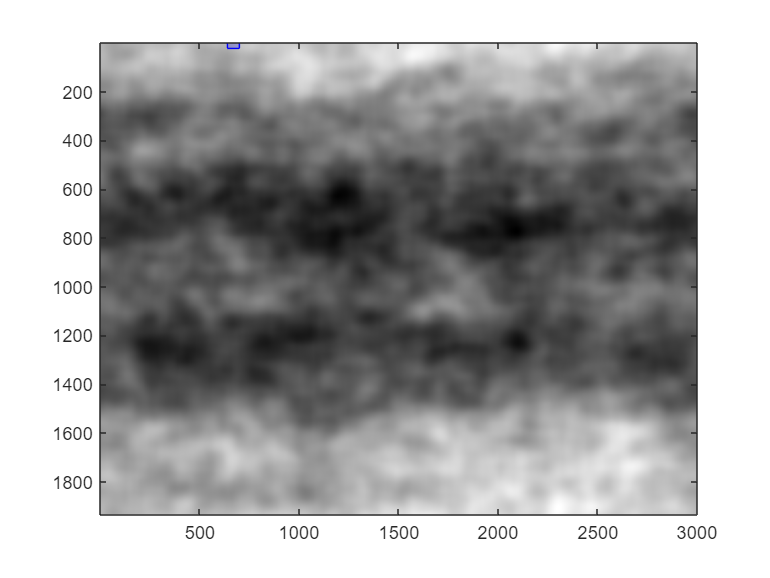

imagesc(imrotate(correlacionOpticaObservable,180))
drawrectangle('Position',[maxX-60,maxY-60,60,60],'Color','b','InteractionsAllowed','none','LineWidth',0.5);

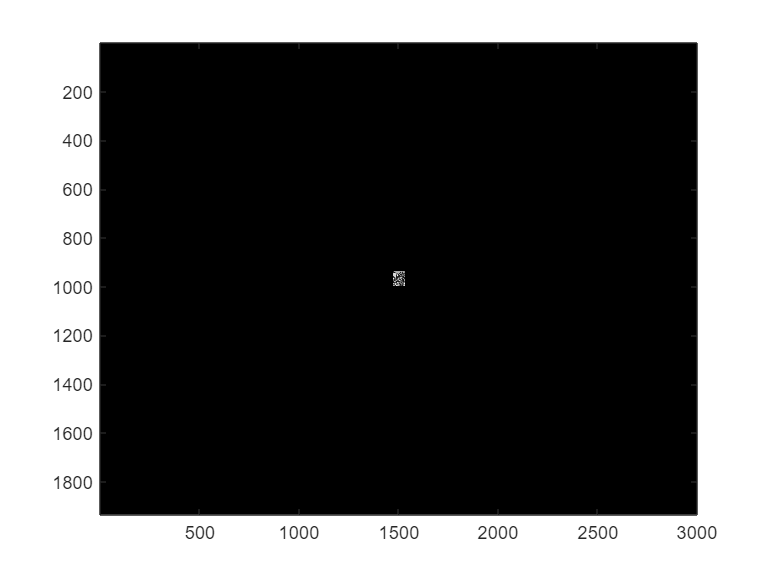


% Intento 2: Conservando el tamaño de clue pero rellenando con ceros (padding)


clueSameSize = padarray(clueBW,double([round(h/2-30), round(w/2-30)]),0,'both');
% take off the last row because big image have odd number of rows
clueSameSize = clueSameSize(1:end-1,:);
imagesc(clueSameSize)

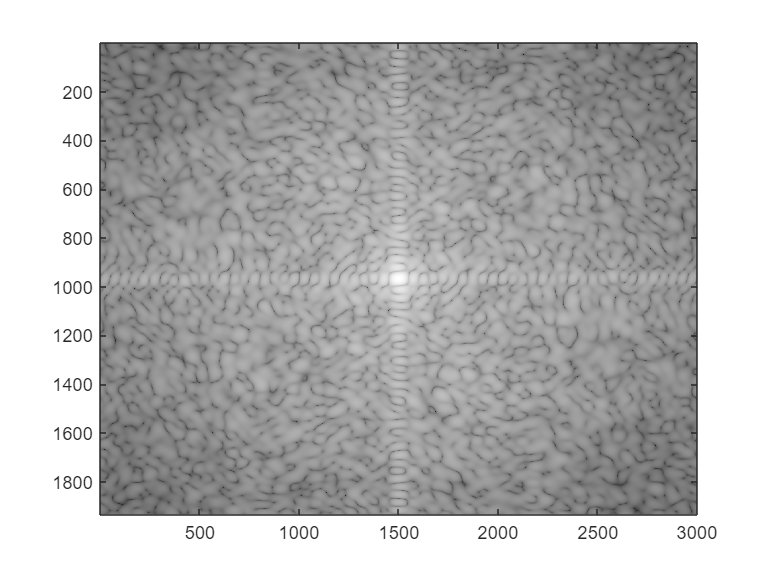

fourierFilterClue = fftshift(fft2(clueSameSize));
imagesc(log(abs(fourierFilterClue)))


% Se hace pasar landscape por el sistema 4f
[~, correlacionOpticaObservable] = sistema4f(landscapeBW, conj(fourierFilterClue));
[maxY,maxX] = find(correlacionOpticaObservable(1:end,:)== max(correlacionOpticaObservable(1:end,:),[],'all'))

maxY =    724
   724


maxX =         1726
        1730


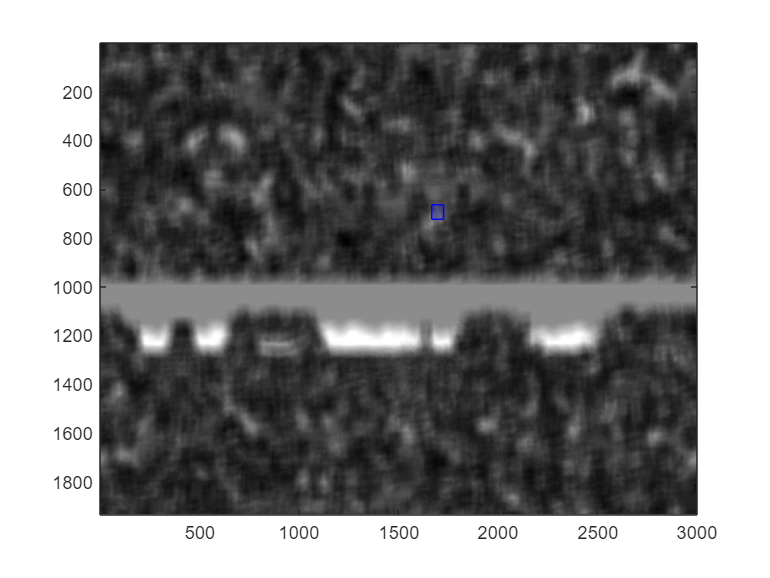

imagesc(imrotate(correlacionOpticaObservable,180))
drawrectangle('Position',[maxX(1)-60,maxY(1)-60,60,60],'Color','b','InteractionsAllowed','none','LineWidth',0.5);

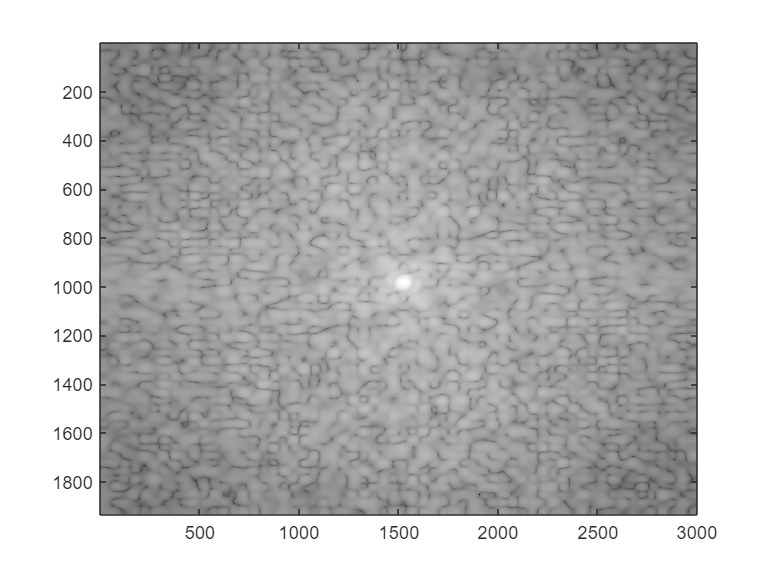


%Intento 3: Sacando la transformada de fourier de clueBW y luego haciendo esa imagen del mismo tamaño de landscape


fourierFilterClue = fftshift(fft2(clueBW));
fourierFilterClue = imresize(fourierFilterClue,[h w]);
imagesc(log(abs(fourierFilterClue)))


%Se hace pasar landscape por el sistema 4f
[~, correlacionOpticaObservable] = sistema4f(landscapeBW, conj(fourierFilterClue));
[maxY,maxX] = find(correlacionOpticaObservable(1:end,:)== max(correlacionOpticaObservable(1:end,:),[],'all'))

maxY = 1695

maxX = 1180

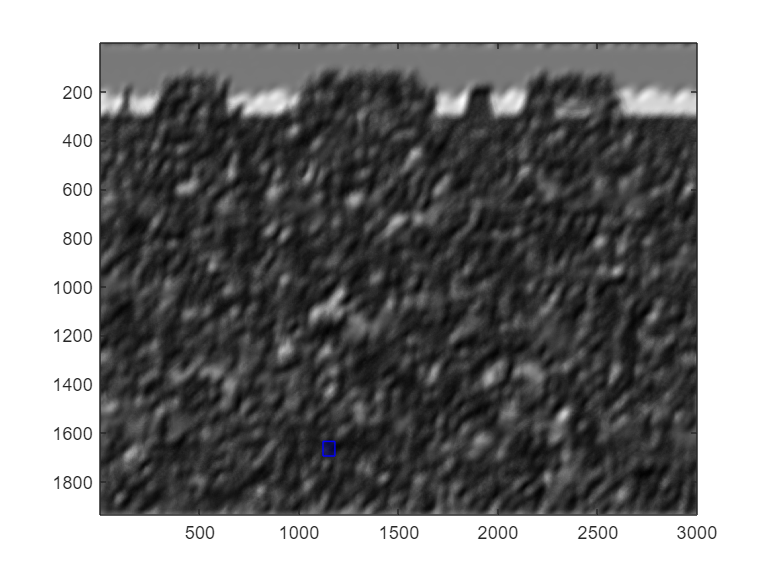

imagesc(imrotate(correlacionOpticaObservable,180))
drawrectangle('Position',[maxX(1)-60,maxY(1)-60,60,60],'Color','b','InteractionsAllowed','none','LineWidth',0.5);

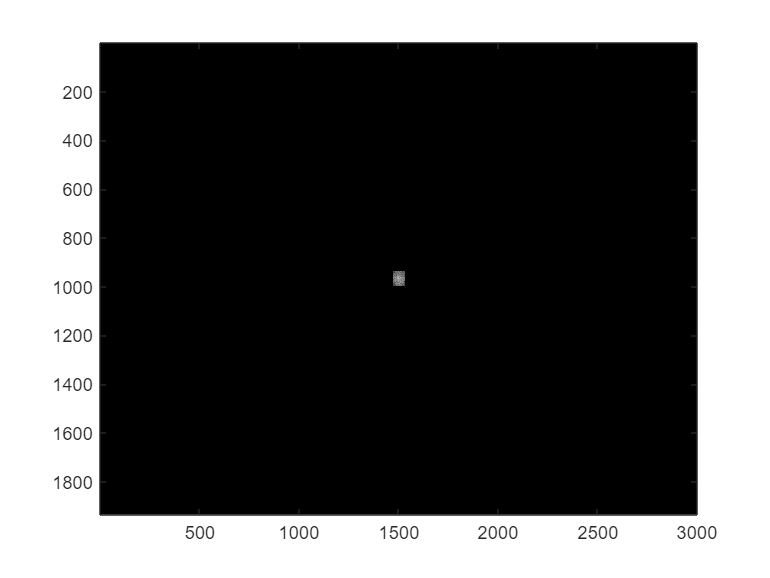

% Intento 4: Sacando la transformada de fourier de clueBW luego rellenando la transformada con ceros 


fourierFilterClue = fftshift(fft2(clueBW));
fourierFilterClue = padarray(fourierFilterClue,double([round(h/2-30), round(w/2-30)]),0,'both');
% take off the last row because big image have odd number of rows
fourierFilterClue = fourierFilterClue(1:end-1,:);
imagesc(log(abs(fourierFilterClue)))


% Se hace pasar landscape por el sistema 4f
[correlacionPura, correlacionOpticaObservable] = sistema4f(landscapeBW, conj(fourierFilterClue));
[maxY,maxX] = find(correlacionOpticaObservable(1:end,:)== max(correlacionOpticaObservable(1:end,:),[],'all'))

maxY = 154

maxX = 387

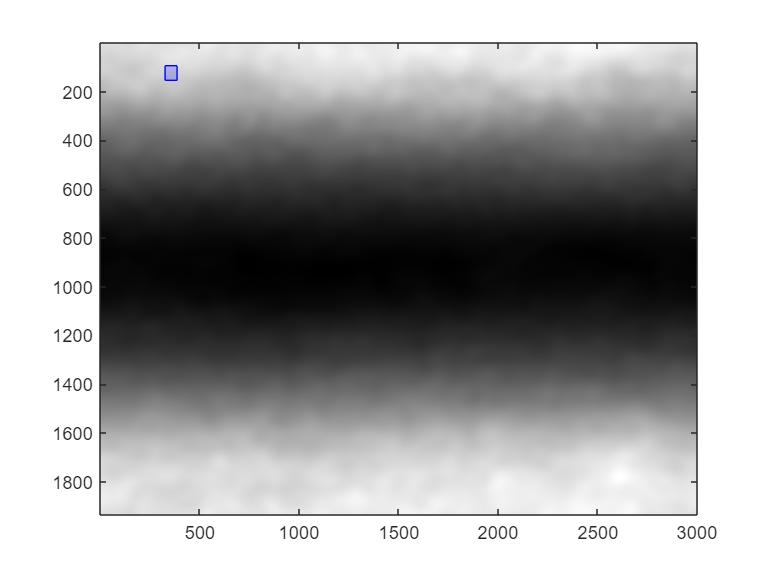

imagesc(imrotate(correlacionOpticaObservable,180))
drawrectangle('Position',[maxX-60,maxY-60,60,60],'Color','b','InteractionsAllowed','none','LineWidth',0.5);

## Realizando la correlacion cruzada normalizada

La correlación cruzada normalizada es un metodo de procesamiento digital de imagenes inspirado en la correlación cruzada pero el factor de peso de cada punto esta afectado por la desviación estandar y la media local 

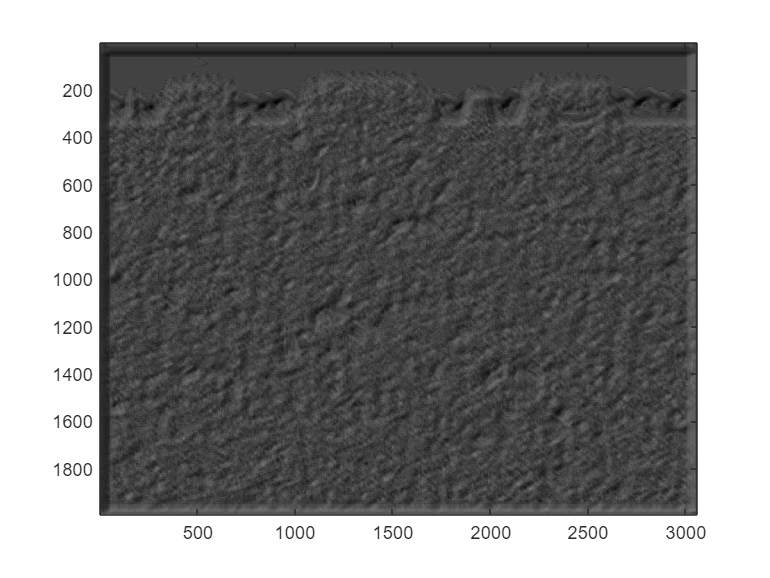

% To perform the calculation we do it in one channel (grayscale)
normCrossCorrelation = normxcorr2(clueBW,landscapeBW);
imagesc(normCrossCorrelation)

maxNormCrossCorrelation = max(normCrossCorrelation,[],"all");
% The maximum is in the right-down edge of the 60x60 zone where the
% correlation is the most
[waldoY,waldoX] = find(normCrossCorrelation==maxNormCrossCorrelation)

waldoY = 1671

waldoX = 431

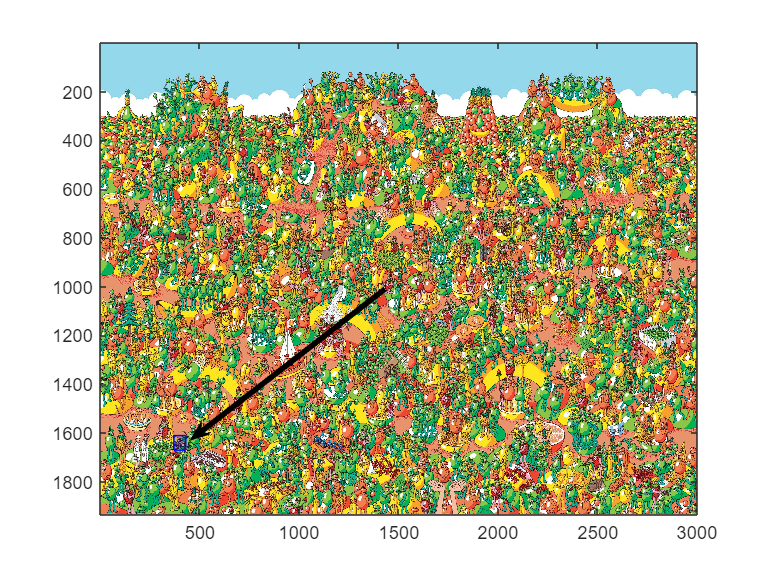

imagesc(landscape)
% Draw the rectangle by the center of the zone of maximum correlation in the color landscape 
drawrectangle('Position',[waldoX-60,waldoY-60,60,60],'Color','b','InteractionsAllowed','none','LineWidth',0.5);
annotation('arrow',[0.5 0.515-((waldoX-30)/1500)],[0.5 0.495-((1933-waldoY-15)/966)],'LineWidth',3)